Planta=tf(22.4,[0.15,1,0])


Planta =
 
      22.4
  ------------
  0.15 s^2 + s
 
Continuous-time transfer function.



Tm=0.05;

Planta_d=c2d(Planta,Tm,'zoh')


Planta_d =
 
    0.1675 z + 0.1499
  ----------------------
  z^2 - 1.717 z + 0.7165
 
Sample time: 0.05 seconds
Discrete-time transfer function.



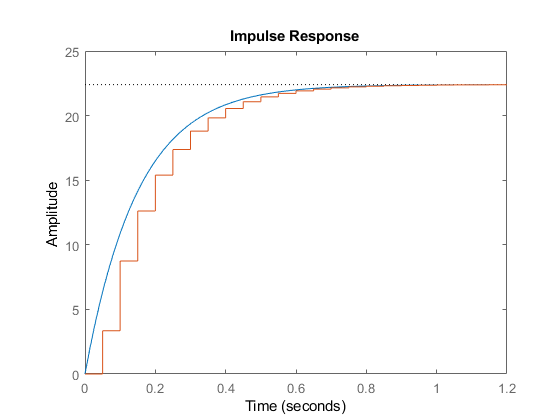


impulseplot(Planta,Planta_d)


Tao=Planta.den{1}/Planta.den{1}(2);
tsla=5*Tao(1);

% tslc=0.6*tsla;
tslc=0.5;

Mp=0.01;

% Parametros de diseño
zhita=sqrt((log(Mp)^2)/(pi^2+log(Mp)^2))

zhita =    0.826085054613957



wn = 4.6/(tslc*zhita);

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



Bd_c=tf(wn^2/(s^2+2*zhita*wn*s+wn^2));
Bd_c=Bd_c/dcgain(Bd_c)


Bd_c =
 
         124
  ------------------
  s^2 + 18.4 s + 124
 
Continuous-time transfer function.




% Bd en discreto
M=exp(-zhita*wn*Tm)

M =    0.631283645506926


Fhi=wn*sqrt(1-zhita^2)*Tm

Fhi =    0.313806561383624



Bd_d=tf(1,[1,-2*M*cos(Fhi),M^2],Tm);
Bd_d=Bd_d/dcgain(Bd_d)


Bd_d =
 
               1
  ---------------------------
  5.061 z^2 - 6.077 z + 2.017
 
Sample time: 0.05 seconds
Discrete-time transfer function.



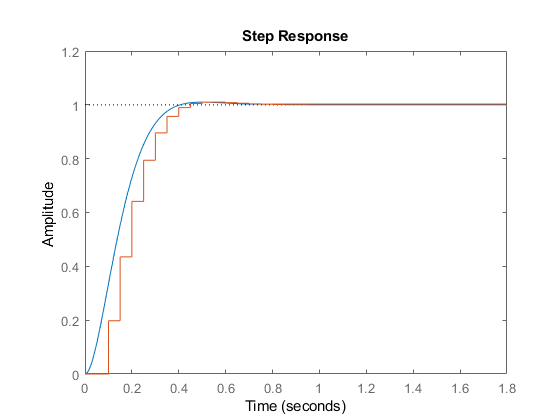


stepplot(Bd_c,Bd_d)


% Parametros obtenidos
Kp = 0.4315026203, ti = 0.09446681833

Kp =    0.431502620300000


ti =    0.094466818330000


z=tf('z',Tm);

PID_d=((Kp + 20.0*Kp*ti)*z - 20.0*Kp*ti)/z


PID_d =
 
  1.247 z - 0.8153
  ----------------
         z
 
Sample time: 0.05 seconds
Discrete-time transfer function.




La_d=PID_d*Planta_d;
Lc_d=feedback(La_d,1)


Lc_d =
 
    0.2089 z^2 + 0.05035 z - 0.1222
  -----------------------------------
  z^3 - 1.508 z^2 + 0.7669 z - 0.1222
 
Sample time: 0.05 seconds
Discrete-time transfer function.




Prefiltro=1/(z-0.653899763433656)/2.889336366599997;

